
close all
N = 5.e3;
n = 25.e2;
% Params report
param_names = {'m', 'mJ', 's2J', 'lambda', 'alpha', 'beta', 'rho', 's2V'};
for k = 1:num_params
    param_vector = test((n + 1):N, k); % Extract samples of the k-th parameter

    mean_val = mean(param_vector);
    std_val = std(param_vector);
    CI = quantile(param_vector, [0.025 0.975]);  % 95% credible interval

    % Display results
    fprintf('%s\n', param_names{k});
    fprintf('Mean: %.6f, Std: %.6f, 95%% CI: [%.6f, %.6f]\n\n', ...
        mean_val, std_val, CI(1), CI(2));
end

m


Mean: 0.250111, Std: 0.287782, 95% CI: [-0.320456, 0.812437]



mJ


Mean: 0.057979, Std: 0.006710, 95% CI: [0.045241, 0.070730]



s2J


Mean: 0.043887, Std: 0.001238, 95% CI: [0.041487, 0.046359]



lambda


Mean: 1.726443, Std: 0.513718, 95% CI: [0.888088, 2.883937]



alpha


Mean: 0.533188, Std: 0.010366, 95% CI: [0.510992, 0.552328]



beta


Mean: -1.025600, Std: 0.029433, 95% CI: [-1.074853, -0.965800]



rho


Mean: -0.456468, Std: 0.024750, 95% CI: [-0.503065, -0.399112]



s2V


Mean: 0.047332, Std: 0.007889, 95% CI: [0.035138, 0.060966]




% V0 and VT
V0_vec = V_path((n + 1):N, 1);
VT_vec = V_path((n + 1):N, end);

mean_V0 = mean(V0_vec);
std_V0 = std(V0_vec);
CI_V0 = quantile(V0_vec, [0.025 0.975]);

fprintf('V0 (initial)\nMean: %.6f, Std: %.6f, 95%% CI: [%.6f, %.6f]\n\n', ...
    mean_V0, std_V0, CI_V0(1), CI_V0(2));

V0 (initial)
Mean: 0.563928, Std: 0.170479, 95% CI: [0.426114, 0.796512]




mean_VT = mean(VT_vec);
std_VT = std(VT_vec);
CI_VT = quantile(VT_vec, [0.025 0.975]);

fprintf('V_T (last)\nMean: %.6f, Std: %.6f, 95%% CI: [%.6f, %.6f]\n', ...
    mean_VT, std_VT, CI_VT(1), CI_VT(2));

V_T (last)
Mean: 0.510189, Std: 0.000000, 95% CI: [0.510189, 0.510189]


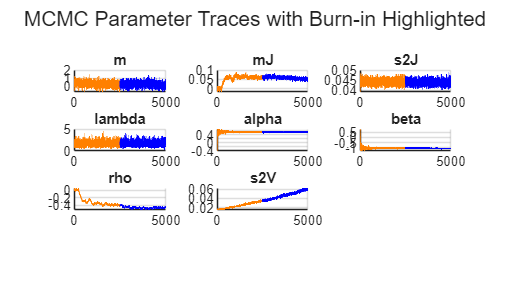



figure('Name','Parameter Paths Across MCMC Iterations')
cut_point = 1;
for k = 1:num_params
    subplot(4,3,k)
    hold on
    plot(cut_point:n, test(cut_point:n,k), 'Color', [1 0.5 0], 'LineWidth', 0.7)  % Burn-in in orange
    plot(n+1:N, test(n+1:N,k), 'b', 'LineWidth', 0.7)  % Post-burnin in blue
    title(param_names{k})
    grid on
    hold off
end

sgtitle('MCMC Parameter Traces with Burn-in Highlighted')
saveas(gcf, 'C:\Thesis\Params trace SVJ (burnin).png')

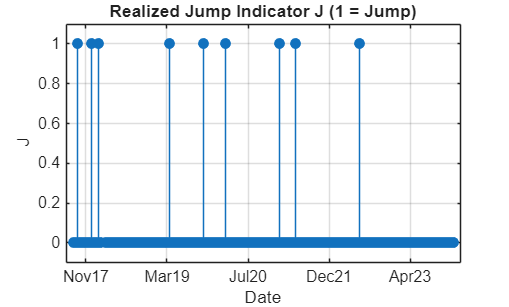


TS = CrixData(2:end,1);

% ===========================
% Time Series Decomposition Plots
% ===========================

% Plot Jump Indicator J
figure
stem(TS, J, 'filled')
datetick('x', 'mmmyy', 'keeplimits', 'keepticks')
ylim([-0.1, 1.1])
title('Realized Jump Indicator J (1 = Jump)')
xlabel('Date')
ylabel('J')
grid on
saveas(gcf, 'C:\Thesis\Jump plot SVJ.png')

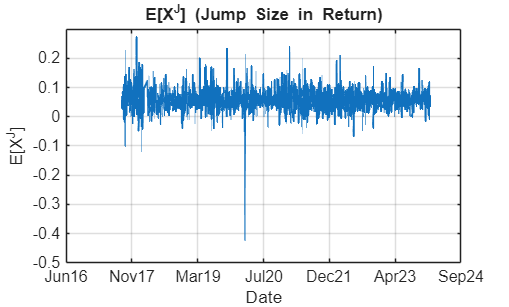



% Plot E[X^J] (Jump Size in Return)
figure
plot(TS, sum(X_path((n+1):N, :), 1)/(N-n), 'LineWidth', 1.2)
datetick('x', 'mmmyy', 'keeplimits', 'keepticks')
title('E[X^J] (Jump Size in Return)')
xlabel('Date')
ylabel('E[X^J]')
grid on
saveas(gcf, 'C:\Thesis\Jump size return plot SVJ.png')

mean(sum(X_path((n+1):N, :), 1)/(N-n))

ans = 0.0578

var(sum(X_path((n+1):N, :), 1)/(N-n))

ans = 0.0013

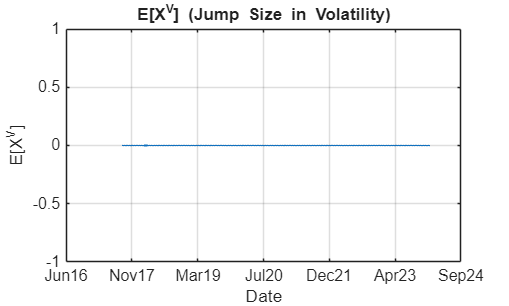


% Plot E[X^V] (Jump Size in Vol)
figure
plot(TS, sum(XV_path((n+1):N, :), 1)/(N-n), 'LineWidth', 1.2)
datetick('x', 'mmmyy', 'keeplimits', 'keepticks')
title('E[X^V] (Jump Size in Volatility)')
xlabel('Date')
ylabel('E[X^V]')
grid on
saveas(gcf, 'C:\Thesis\Jump size vol plot SVJ.png')

mean(sum(XV_path((n+1):N, :), 1)/(N-n))

ans = 0


% Expectation Calculations
eX = sum(X_path((n+1):N, :), 1)'/(N-n);
eXV = sum(XV_path((n+1):N, :), 1)'/(N-n);
eJ = round(sum(J_path((n+1):N, :), 1)'/(N-n));
eV = sum(V_path((n+1):N, :), 1)'/((N-n) * 365);

% Decomposed Jump Contributions
Jump_P = eX .* eJ;    % Return Jump
Jump_V = eXV .* eJ;   % Volatility Jump

% Residual Calculation for SVJ
Sig = sqrt(eV);
ResY = (Y(2:end) - m - Jump_P(2:end)) ./ Sig(1:end-1);

% GARCH estimation
Mdl = garch(1,1);
EstMdl = estimate(Mdl, Y);

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    6.8883e-05     6.8883e-06            10      1.5222e-23
    GARCH{1}       0.86432       0.010673        80.979               0
    ARCH{1}       0.097664      0.0068875         14.18      1.2181e-45



vG = infer(EstMdl, Y);
Res_G = Y ./ sqrt(vG);

% MSE Comparison
MSE_SVJ = mse(eV, Y.^2);
MSE_G = mse(vG, Y.^2);

% Sort the residuals
residuals_logr = sort((Y(2:end)- mean(Y)) / std(Y));
residuals_GARCH = sort(Res_G(2:end));
residuals_SVJ = sort(ResY);  % Or Res_G, or 
% Get theoretical quantiles
n = length(residuals_logr);
theoretical_q = norminv(((1:n) - 0.5) / n, 0, 1);  % Standard normal

% Compute MSE between quantiles
residuals_SVJ = sort(residuals_SVJ(:));     % force column
theoretical_q = theoretical_q(:);             % force column
w = abs(theoretical_q);                       % also column
qq_logr_mse = mean((residuals_logr - theoretical_q).^2)

qq_logr_mse = 0.1032

qq_GARCH_mse = mean((residuals_GARCH - theoretical_q).^2)

qq_GARCH_mse = 0.1007

qq_SVJ_mse = mean((residuals_SVJ - theoretical_q).^2)

qq_SVJ_mse = 0.0386

qq_logr_mse_weighted = mean((w .* (residuals_logr - theoretical_q)).^2)

qq_logr_mse_weighted = 0.7012

qq_GARCH_mse_weighted = mean((w .*(residuals_GARCH - theoretical_q)).^2)

qq_GARCH_mse_weighted = 0.7351

qq_SVJ_mse_weighted = mean((w .* (residuals_SVJ - theoretical_q)).^2)

qq_SVJ_mse_weighted = 0.0481



% Create a new figure for SVJ Variance Estimation
figure('Name', 'Variance Estimation: SVJ', 'Color', 'w');

% Plot the estimated variance
plot(TS, eV * 365, 'LineWidth', 1.5, 'DisplayName', 'E[V] (SVJ)');
datetick('x', 'mmmyy', 'keeplimits', 'keepticks');
xlabel('Date', 'FontSize', 11);
ylabel('Variance', 'FontSize', 11);
title('Estimated Variance under SVJ Model', 'FontSize', 13);
grid on;
mean(eV*365)

ans = 0.5197

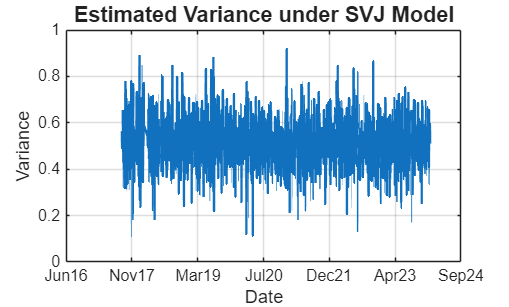

% Save the figure as PNG
saveas(gcf, 'C:\Thesis\Variance plot SVJ.png');

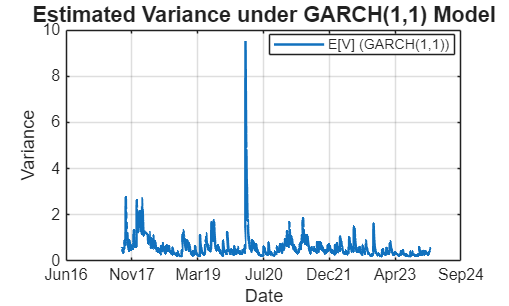


% Create a new figure for SVJ Variance Estimation
figure('Name', 'Variance Estimation: GARCH(1,1)', 'Color', 'w');

plot(TS, vG * 365, 'LineWidth', 1.5, 'DisplayName', 'E[V] (GARCH(1,1))');
datetick('x', 'mmmyy', 'keeplimits', 'keepticks');
xlabel('Date', 'FontSize', 11);
ylabel('Variance', 'FontSize', 11);
title('Estimated Variance under GARCH(1,1) Model', 'FontSize', 13);
legend('Location', 'best');
grid on;

% Save the figure as PNG
saveas(gcf, 'C:\Thesis\Variance plot GARCH.png');

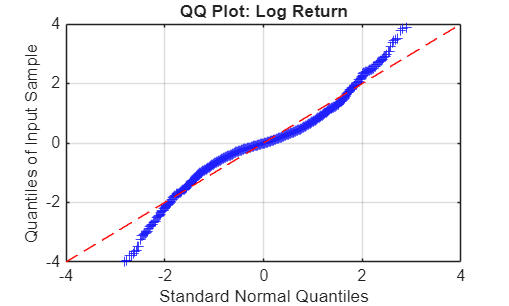


% ----------------------
% Manual Q-Q Plot: Log Return
% ----------------------
res_logr = (Y(2:end) - mean(Y)) / std(Y);
res_logr_sorted = sort(res_logr);
n_logr = length(res_logr_sorted);
q_theoretical_logr = norminv(((1:n_logr) - 0.5) / n_logr);

figure('Name','QQ Plot: Log Return (Manual)')
plot(q_theoretical_logr, res_logr_sorted, 'b+')
hold on
plot([-4, 4], [-4, 4], 'r--')  % 45-degree line
xlim([-4, 4]); ylim([-4, 4])
xlabel('Standard Normal Quantiles')
ylabel('Quantiles of Input Sample')
title('QQ Plot: Log Return')
grid on
saveas(gcf, 'C:\Thesis\qqplot_Logr_manual.png')

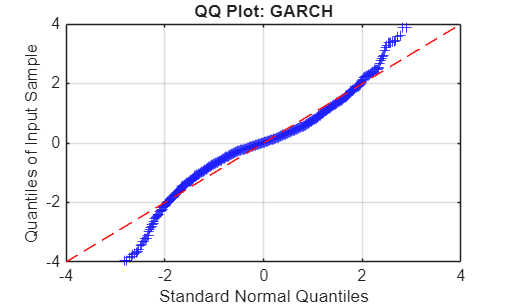



% ----------------------
% Manual Q-Q Plot: GARCH Residuals
% ----------------------
res_G_sorted = sort(Res_G);
n_garch = length(res_G_sorted);
q_theoretical_garch = norminv(((1:n_garch) - 0.5) / n_garch);

figure('Name','QQ Plot: GARCH (Manual)')
plot(q_theoretical_garch, res_G_sorted, 'b+')
hold on
plot([-4, 4], [-4, 4], 'r--')
xlim([-4, 4]); ylim([-4, 4])
xlabel('Standard Normal Quantiles')
ylabel('Quantiles of Input Sample')
title('QQ Plot: GARCH')
grid on
saveas(gcf, 'C:\Thesis\qqplot_GARCH_manual.png')

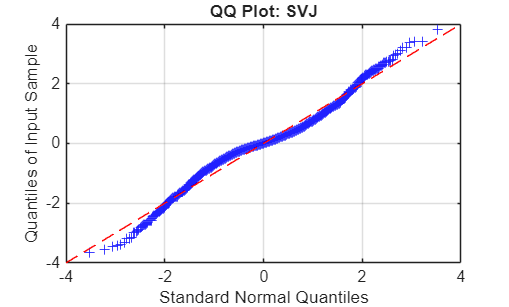



% ----------------------
% Manual Q-Q Plot: SVJ Residuals
% ----------------------
res_SVJ = ResY;  % Standardize
res_SVJ_sorted = sort(res_SVJ);
n_SVJ = length(res_SVJ_sorted);
q_theoretical_SVJ = norminv(((1:n_SVJ) - 0.5) / n_SVJ);

figure('Name','QQ Plot: SVJ (Manual)')
plot(q_theoretical_SVJ, res_SVJ_sorted, 'b+')
hold on
plot([-4, 4], [-4, 4], 'r--')
xlim([-4, 4]); ylim([-4, 4])
xlabel('Standard Normal Quantiles')
ylabel('Quantiles of Input Sample')
title('QQ Plot: SVJ')
grid on
saveas(gcf, 'C:\Thesis\qqplot_SVJ_manual.png')